% This is the CPX1 Matlab Live Script - SIGNAL x2
% This file analyzes the first signal, x2
%
% Note that this was written as a live script, and thus prints values and
% plots to the screen for easy access
% 
% While writing a function would have enabled code to be reused, it was
% determined that the more important factor was easy accessibility to the
% plots, and any function would have required a large number of input
% values
%
% See the other files for the analysis of x3 and x4, the files were
% separated due to the intense memory requirements to display all of the
% plots
%
% Almost all plots have the frequency bins above the time/frequency values,
% as that enabled easy zooming in

% ================ Setup ================ %

cd("C:\Users\C25Dante.Cometto\OneDrive - afacademy.af.edu\Documents\1 Important\3 School 2024F\5 ECE 434\CPX2")
load cpx2.bin -mat
who


Your variables are:

Fs     Fs_x3  Fs_x4  Fs_x7  Fs_x8  ans    x1     x2     x3     x4     x7     x8     



Fs

Fs = 8000

Fs_x8 = 11025


color1 = "#77A890"

color1 = "#77A890"

color2 = "#26503C"

color2 = "#26503C"

color3 = "#F9F5E9"

color3 = "#F9F5E9"

color4 = "#9E816B"

color4 = "#9E816B"

color5 = "#C15441"

color5 = "#C15441"

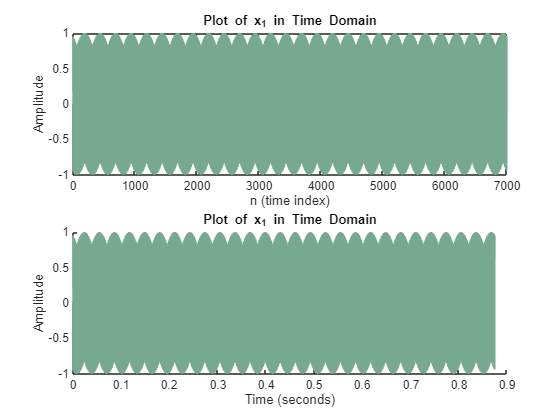

% =========================== For signal x1 ===========================
x1;
n1 = 0:length(x1)-1;
dt1 = 1/Fs;
t1 = n1*dt1;
X1 = fft(x1);
k1 = n1;
df1 = Fs/length(k1); % Fs/N
f1 = k1*df1;
X1db = 20*log10(abs(X1)/max(abs(X1)));

% ===== Begin by plotting in time domain =====
figure
subplot(2,1,1)
plot(n1,x1,"Color",color1)
title("Plot of x_1 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t1,x1,"Color",color1)
title("Plot of x_1 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

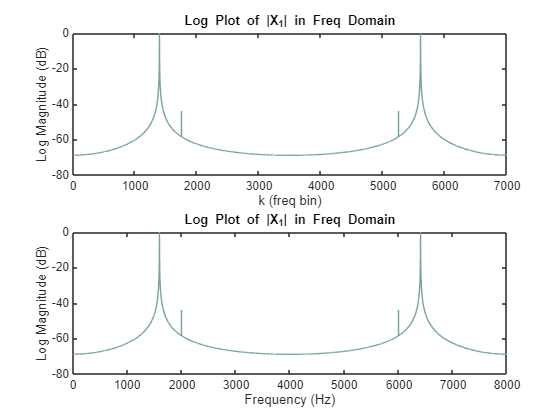


% Zoom in for report!!!

% dB plot
figure
subplot(2,1,1)
plot(k1,X1db,"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")
subplot(2,1,2)
plot(f1,X1db,"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Zoom in
a = 1350

a = 1350

b = 1800

b = 1800

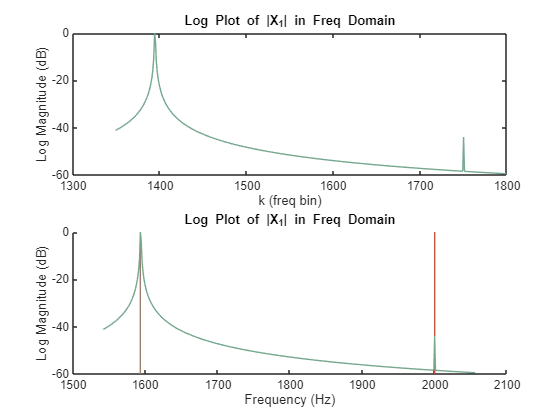


figure
subplot(2,1,1)
plot(k1(a:b),X1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([1593 1593],[-60 0],"Color",color4)
plot([2000 2000],[-60 0],"Color",color5)
plot(f1(a:b),X1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% => Freqs are at 1593 Hz and 2000 Hz

sound(x1)

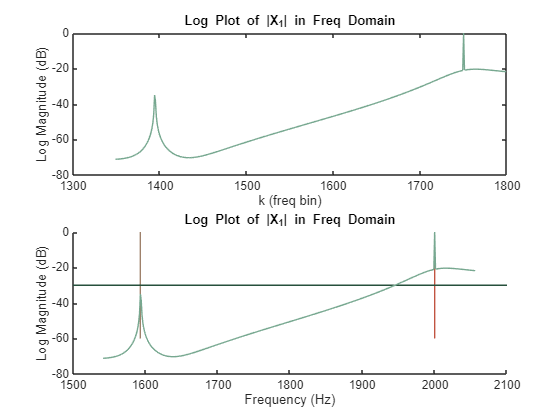

% Now, apply filter for x1
load filter_x1.bin -mat

fx1 = filter(num_x1,den_x1,x1);
fX1 = fft(fx1);
fX1db = 20*log10(abs(fX1)/max(abs(fX1)));

% Changelog:
% v1 - just over -30dB, order 7
% v2 - well below -30db, order 7

% And plot again

figure
subplot(2,1,1)
plot(k1(a:b),fX1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([1593 1593],[-60 0],"Color",color4)
plot([2000 2000],[-60 0],"Color",color5)
plot([1500 2100],[-30 -30],"Color",color2)
plot(f1(a:b),fX1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% sound is now the higher tone
sound(100*fx1)

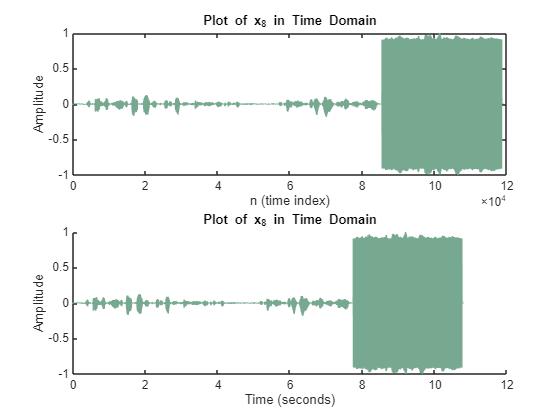

% =========================== For signal x8 ===========================
% Fix FS!!!!
x8;
n8 = 0:length(x8)-1;
dt8 = 1/Fs_x8;
t8 = n8*dt8;
X8 = fft(x8);
k8 = n8;
df8 = Fs_x8/length(k8); % Fs/N
f8 = k8*df8;
X8db = 20*log10(abs(X8)/max(abs(X8)));

% ===== Begin by plotting in time domain =====
figure
subplot(2,1,1)
plot([82500 82500],[-0.5 0.5],"Color",color5)
plot(n8,x8,"Color",color1)
title("Plot of x_8 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t8,x8,"Color",color1)
title("Plot of x_8 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

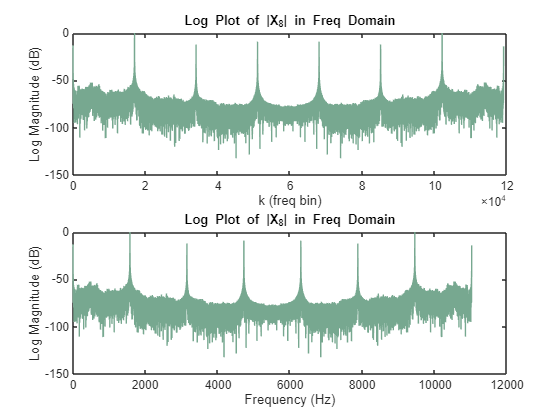


% Zoom in for report!!!

% dB plot
figure
subplot(2,1,1)
plot(k8,X8db,"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")
subplot(2,1,2)
plot(f8,X8db,"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")

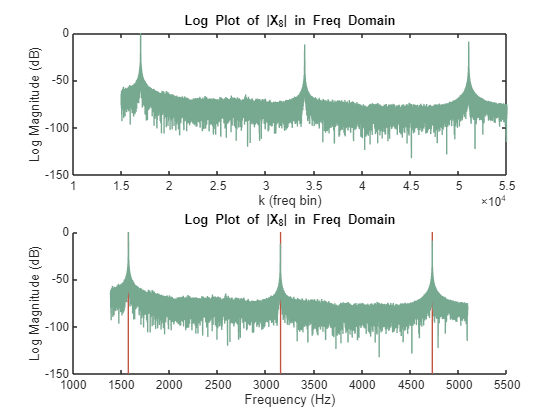


% Zoom in and label
a = 15000;
b = 55000;

t1 = 1142*11025/8000;
t2 = 2287*11025/8000;
t3 = 3429*11025/8000;

figure
subplot(2,1,1)
plot(k8(a:b),X8db(a:b),"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([t1 t1],[-150 0],"Color",color5)
plot([t2 t2],[-150 0],"Color",color5)
plot([t3 t3],[-150 0],"Color",color5)
plot(f8(a:b),X8db(a:b),"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Calculate normalized angular freq for pole-zero plot
w1 = t1/Fs_x8*2*pi

w1 = 0.8969

w2 = t2/Fs_x8*2*pi

w2 = 1.7962

w3 = t3/Fs_x8*2*pi

w3 = 2.6931

w1/2

ans = 0.4485

(w1+w2)/2

ans = 1.3466

(w2+w3)/2

ans = 2.2447

(w3+pi)/2

ans = 2.9174


%sound(x8)
% It's been 8 years upon a project for extracting sunbeams out of cucumbers.
%  He told me he did not doubt that in 8 years more ------

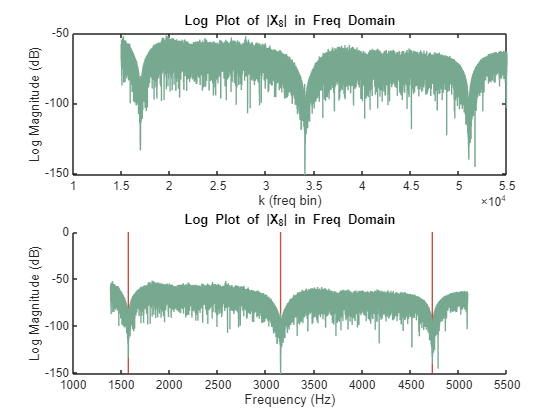

% Now, apply filter for x8
load filter_x8.bin -mat

fx8 = filter(num_x8,den_x8,x8);
fX8 = fft(fx8);
fX8db = 20*log10(abs(fX8)/max(abs(fX8)));

% Changelog:
% v1 - just barely missed the tones, looks like too high on all three, order 6 
% v2 - much better, but still not perfectly clear and can hear a tone, order 6
% v3 - can almost hear everything, still one tone, order 6
% v4 - removes tones better, but garbles audio, order 12
% v5 - beautifully removes tones, but audible clicks.  Order 12

% And plot again

figure
subplot(2,1,1)
plot(k8(a:b),fX8db(a:b),"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([t1 t1],[-150 0],"Color",color5)
plot([t2 t2],[-150 0],"Color",color5)
plot([t3 t3],[-150 0],"Color",color5)
plot(f8(a:b),fX8db(a:b),"Color",color1)
title("Log Plot of |X_8| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")

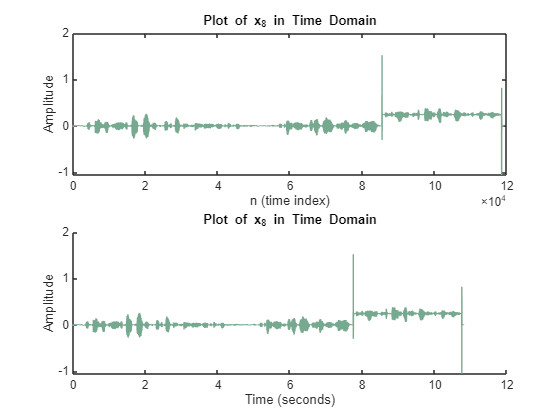


% And time plot too
figure
subplot(2,1,1)
plot(n8,fx8,"Color",color1)
title("Plot of x_8 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t8,fx8,"Color",color1)
title("Plot of x_8 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

% could work on smoothing out that click and amplitude difference... is
% that DC interference?  Oh, a tone at DC?  Yes, there is a tone at DC.
% Minimizes order to not remove, all information still gotten

% sound is now the higher tone
sound(fx8)
% It's been 8 years upon a project for extracting sunbeams out of cucumbers.
%  He told me he did not doubt that in 8 years more he should be able to suuply the governor's daughters with sunshine

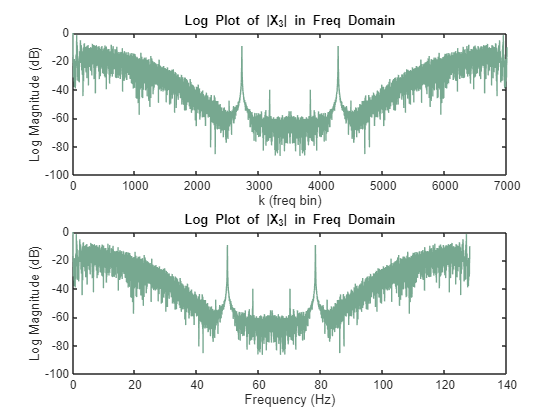

% x3 - ECG

% =========================== For signal x3 ===========================
x3;
n3 = 0:length(x3)-1;
dt3 = 1/Fs_x3;
t3 = n3*dt3;
X3 = fft(x3);
k3 = n3;
df3 = Fs_x3/length(k3); % Fs/N
f3 = k3*df3;
X3db = 20*log10(abs(X3)/max(abs(X3)));

% ===== Begin by plotting in time domain =====

% Zoom in for report!!!

% dB plot
figure
subplot(2,1,1)
plot(k3,X3db,"Color",color1)
title("Log Plot of |X_3| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")
subplot(2,1,2)
plot(f3,X3db,"Color",color1)
title("Log Plot of |X_3| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Note that contamination occurs at 50 Hz


% Zoom in
a = 2500

a = 2500

b = 2900

b = 2900

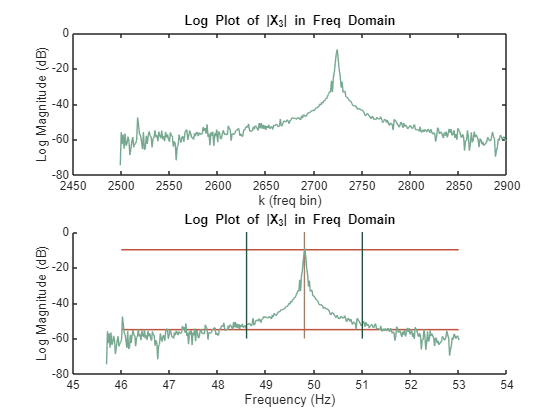


figure
subplot(2,1,1)
plot(k3(a:b),X3db(a:b),"Color",color1)
title("Log Plot of |X_3| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([49.8 49.8],[-60 0],"Color",color4)
plot([46 53],[-10 -10],"Color",color5)
plot([46 53],[-55 -55],"Color",color5)
plot(f3(a:b),X3db(a:b),"Color",color1)
plot([48.6 48.6],[-60 0],"Color",color2)
plot([51 51],[-60 0],"Color",color2)
title("Log Plot of |X_3| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Centered around 49.8 Hz
% Reaches from 48.6 to 51
% Peak is at -15 db
% Data is at -55 db

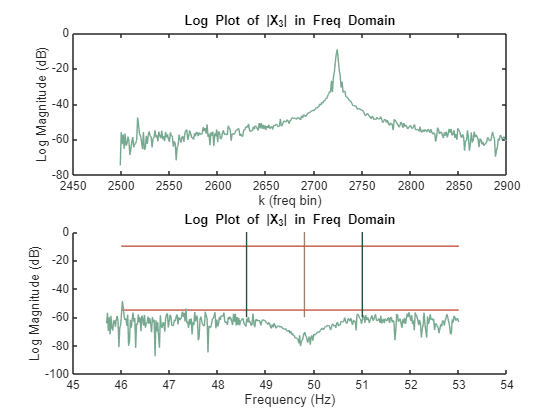

% Now, apply filter for x3
load filter_x3.bin -mat

fx3 = filter(num_x3,1,x3);
fX3 = fft(fx3);
fX3db = 20*log10(abs(fX3)/max(abs(fX3)));

% Changelog:
% v1 - took out way too much and super high order 252
% v2- better, cleans up data nicely, too destructive, 94
% v3 - doesn't remove peak, suppresses data too much, 24
% v4 - just barely removes too much, 66
% v5 - better, 76
% v6 - the -60db spike is clearly visible, 102
% v6b - better than v6, much more narrow effect 98 ^^ equiripple
% v7 - changed to LSE, not better, 90
% currently using v6b

% And plot again

figure
subplot(2,1,1)
plot(k3(a:b),X3db(a:b),"Color",color1)
title("Log Plot of |X_3| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([49.8 49.8],[-60 0],"Color",color4)
plot([46 53],[-10 -10],"Color",color5)
plot([46 53],[-55 -55],"Color",color5)
plot(f3(a:b),fX3db(a:b),"Color",color1)
plot([48.6 48.6],[-60 0],"Color",color2)
plot([51 51],[-60 0],"Color",color2)
title("Log Plot of |X_3| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")

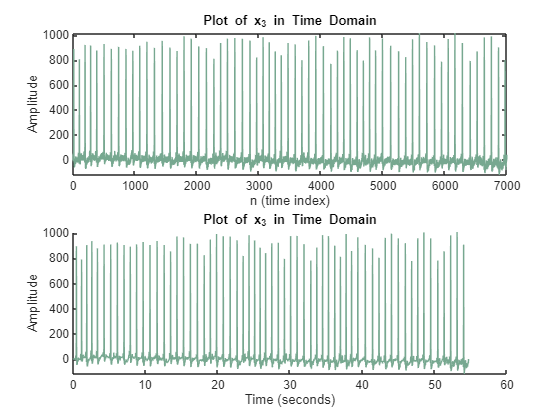


% And time plot too
figure
subplot(2,1,1)
plot(n3,x3,"Color",color1)
title("Plot of x_3 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t3,fx3,"Color",color1)
title("Plot of x_3 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off


% zoom in

a = 10

a = 10

b = 266

b = 266

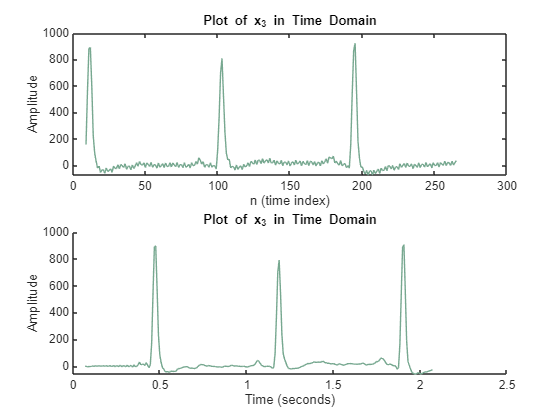


figure
subplot(2,1,1)
plot(n3(a:b),x3(a:b),"Color",color1)
title("Plot of x_3 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t3(a:b),fx3(a:b),"Color",color1)
title("Plot of x_3 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off